This document attempts to apply DMD first from a spatial viewpoint and then from a temporal one.

First we start with time-resolved PIV measurements. It is known that DMD can be applied to these datasets. This is applied for N = 8000.

% Load velocity data
clear all;
completeName = 'Y:\rawdata\Sandia_cavity\Denoise velocity data\tr_POD\Mach0.8\vel_fluc.txt';
uv = load(completeName);

% Extract first 8000 snapshots and apply SVD on it
uv1 = uv;
uv_m = mean(uv1,2);
uv1 = uv1 - uv_m;
[Qx_1, S_1, V_1] = svd(uv1,0);

Now, extract non time-resolved velocity datasets and apply svd on it to get the left singular vector,

% Load data
completeName = 'Y:\rawdata\Sandia_cavity\Denoise velocity data\ensemble_POD\Mach0.8\vel_fluc.txt';
uv_e = load(completeName);

% Apply svd
uv_m = mean(uv_e,2);
uv_e = uv_e - uv_m;
[Qx_e, S_e, V_e] = svd(uv_e,0);

Now, we compare the left singular vector from time-resolved and non time-resolved data

abs(dot(Qx_e(:,1:20),Qx_1(:,1:20)))

ans =     0.9990    0.9976    0.9753    0.9731    0.8209    0.8231    0.9722    0.8955    0.8340    0.8877    0.8864    0.8403    0.8430    0.9184    0.5592    0.6283    0.8861    0.7538    0.5762    0.6473


Now, we take spatially non resolved data and apply svd to get right singular vector

% Modify data to make it non spatially resolved
uv2 = uv(1:50:6360,:);

% Apply svd
uv_m = mean(uv2,2);
uv2 = uv2 - uv_m;
[Qx2, S2, V2] = svd(uv2,0);

We compare the right singular vectors with spatially resolved velocity datasets,

abs(dot(V_1(:,1:10),V2(:,1:10)))

ans =     0.9924    0.9857    0.9797    0.9646    0.9266    0.9304    0.8112    0.0721    0.1016    0.4072


We now evaluate Atilde. SOME ERROR CALCULATING THE EIGENVECTORS AND EIGENVALUES. 

%
Qx1 = Qx_e(:,1:8);
y = uv(:,2:31);
V1 = V2(1:30,1:8);
S1 = S2(1:8,1:8)./0.1427;
Atilde = Qx1' * y * V1 * pinv(S1);% (385x6360)x(6360x385)x(385x385)x(385x385)

We now get eigenvalues and eigenvectors from Atilde matrix

[dmd_vec,dmd_eval1] = eig(Atilde);

Compare this with the Atilde with velocity fluctuations

Qx3 = Qx_1(:,1:8);
y = uv(:,2:31);
V3 = V_1(1:30,1:8);
S3 = S_1(1:8,1:8);
Atilde1 = Qx3' * y * V3 * pinv(S3);
[dmd_vec1,dmd_eval11] = eig(Atilde1);

Reconstruct the velocity fields

dmd_modes1 = y*V3/S3*dmd_vec1;
dmd_modes = y*V1/S1*dmd_vec;

Plotting the eigenvectors on the coordinate space of the cavity gives a better idea,

% Plot 1
% Use format_graph function

N = 1;
A_rec = (dmd_modes)*(dmd_eval1^N)*pinv(dmd_modes);
Y_rec = A_rec*uv(:,1:30);
Y_rec_r = real(Y_rec);
A_rec1 = (dmd_modes1)*(dmd_eval11^N)*pinv(dmd_modes1);
Y_rec1 = A_rec1*uv(:,1:30);
Y_rec_r1 = real(Y_rec1);


In this section, we compare the two in terms of velocity reconstructions,

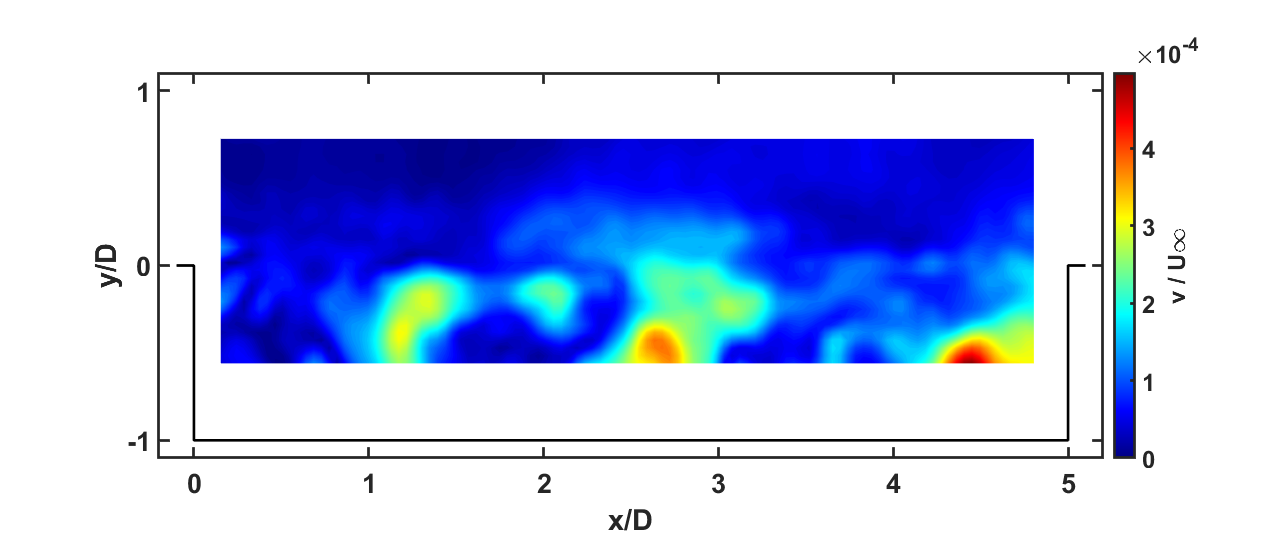

% Plot vrms for the first,
vrms1 = rms(Y_rec_r,2);
vrms2 = rms(Y_rec_r1,2);
vrms = rms(y,2);
figure();
plot_cont_rms(vrms1,2);

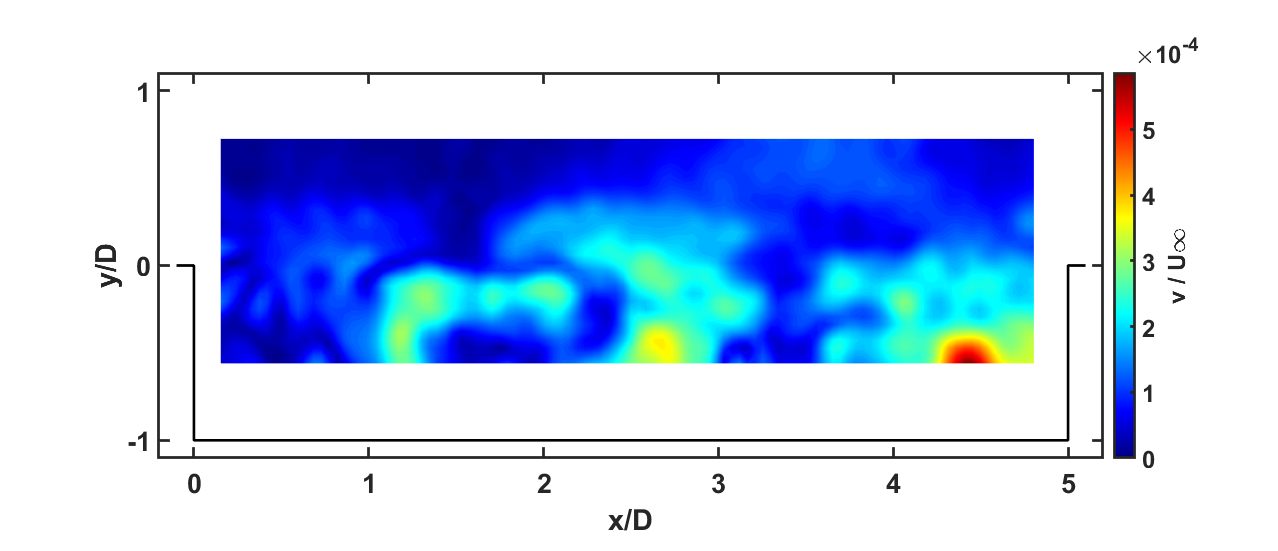

figure();
plot_cont_rms(vrms2,2);

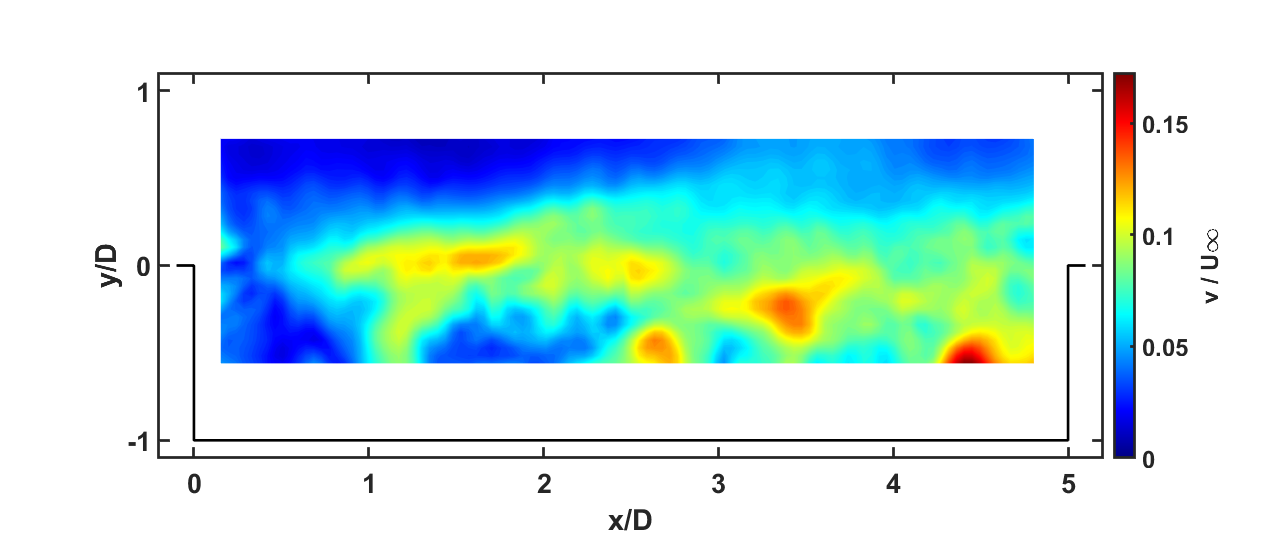

figure()
plot_cont_rms(vrms,2);

% Plot vrms for the case when we only have small amount of data,
uv_i = uv(:,1:31);
uv_mi = mean(uv_i,2);
uv_i1 = uv_i - uv_mi;
xi = uv_i1(:,1:30);
yi = uv_i1(:,2:31);
[Qx_i, S_i, V_i] = svd(xi,0);
Qxii = Qx_i(:,1:8);
Vii = V_i(1:30,1:8);
Sii = S_i(1:8,1:8);
Atildei = Qxii' * yi * Vii * pinv(Sii);
[dmd_veci,dmd_evali] = eig(Atildei);
dmd_modesi = yi*Vii/Sii*dmd_veci;

N = 1;
A_reci = (dmd_modesi)*(dmd_evali^N)*pinv(dmd_modesi);
Y_reci = A_rec*xi;
Y_rec_ri = real(Y_rec);
vrmsi = rms(Y_rec_ri,2);
figure()
plot_cont_rms(vrmsi,2);